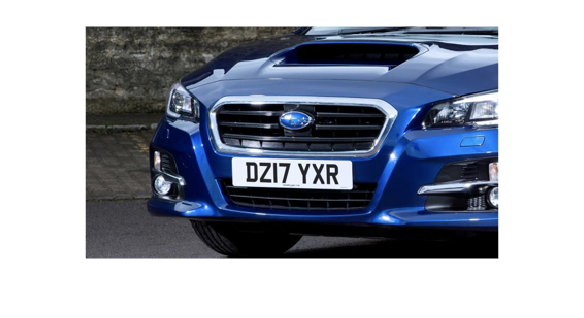

clear all;
f = imread("car_images/Good_img/Cars3.png");
imshow(f)

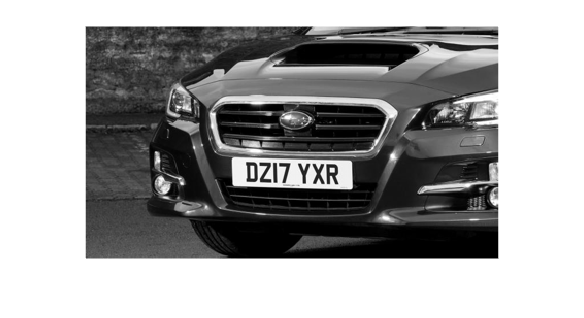

f2 = rgb2gray(f);
imshow(f2)

function cornerpoints = getCornersLicense(grayImg)
    %Binarize image and isolate the license plate
    f3 = imadjust(f2, [0.75 1], [0 1]);
    f3 = imbinarize(f3);
    CC = bwconncomp(f3);
    
    numPixels = cellfun(@numel, CC.PixelIdxList);
    [biggest, idx] = max(numPixels);
    for k = 1:length(numPixels)
        if k ~= idx
            f3(CC.PixelIdxList{k}) = 0;
        end
    end

    %Hide the letters to get better corner detection
    f4 = imfill(f3, "holes");

    %Detect the 4 corners of the license plate
    points = detectBRISKFeatures(f4);
    mainpoints = points.selectStrongest(30).Location;

    [toppoint, topidx] = max(mainpoints(:,2));
    [bottompoint, bottomidx] = min(mainpoints(:,2));
    [leftpoint, leftidx] = min(mainpoints(:,1));
    [rightpoint, rightidx] = max(mainpoints(:,1));
    
    cornerpoints = [mainpoints(topidx,:); mainpoints(rightidx,:); mainpoints(bottomidx,:); mainpoints(leftidx,:)]
end

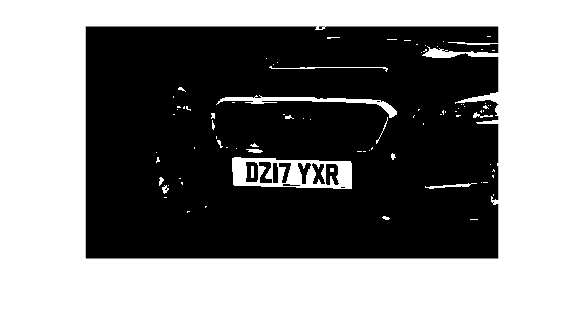


%Binarize image and isolate the license plate
f3 = imadjust(f2, [0.75 1], [0 1]);
f3 = imbinarize(f3);
imshow(f3)

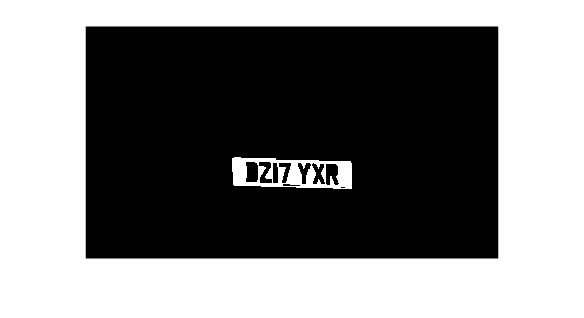

CC = bwconncomp(f3);

numPixels = cellfun(@numel, CC.PixelIdxList);
[biggest, idx] = max(numPixels);
for k = 1:length(numPixels)
    if k ~= idx
        f3(CC.PixelIdxList{k}) = 0;
    end
end
imshow(f3)

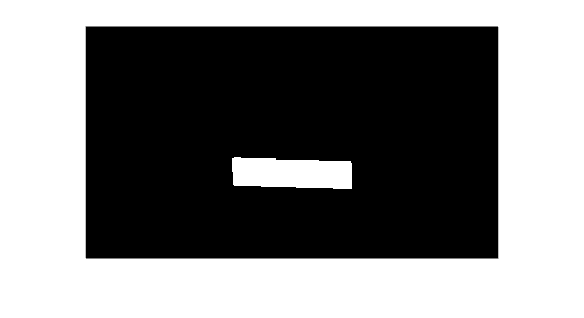

%Hide the letters to get better corner detection
f4 = imfill(f3, "holes");
imshow(f4)

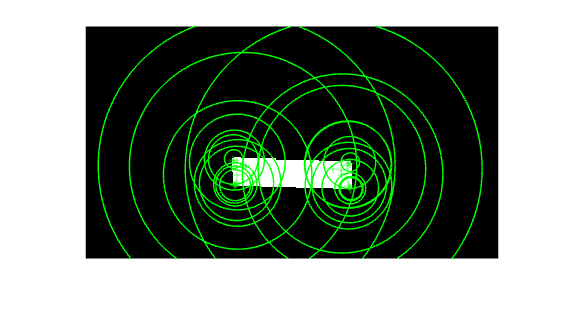

%Detect the 4 corners of the license plate
points = detectBRISKFeatures(f4);
figure(1); imshow(f4);
hold on;
plot(points.selectStrongest(30));

mainpoints = points.selectStrongest(30).Location;


[toppoint, topidx] = max(mainpoints(:,2));
[bottompoint, bottomidx] = min(mainpoints(:,2));
[leftpoint, leftidx] = min(mainpoints(:,1));
[rightpoint, rightidx] = max(mainpoints(:,1));

fourcorners = [mainpoints(topidx,:); mainpoints(rightidx,:); mainpoints(bottomidx,:); mainpoints(leftidx,:)]

fourcorners = 4×2 single matrix
  258.0000  158.0000
  258.0000  158.0000
  144.0000  129.0000
  143.5000  129.5000


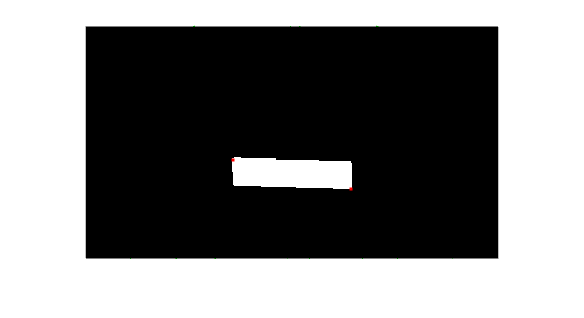


figure(2); imshow(f4);
hold on;
plot(fourcorners(:,1),fourcorners(:,2),'r.');